# Three Node Network inversion with TAPAS

## Simulate resting state data for three node network

As done in Frässle et al. (2021) using function created code from SPM's `DEM_demo_induced_fMRI.m `to generate resting state time series.

stim_options = get_default_stim_options();
type = 'r'; % setting to 'r' instead of 's' until bug is fixed
cmap = mycmap();

Generate data using AR(1) process and inhibititory self-connections.

[DCM, options] = make_DEM_demo_induced_fmri(stim_options);

Visualize simulated graph and BOLD data.

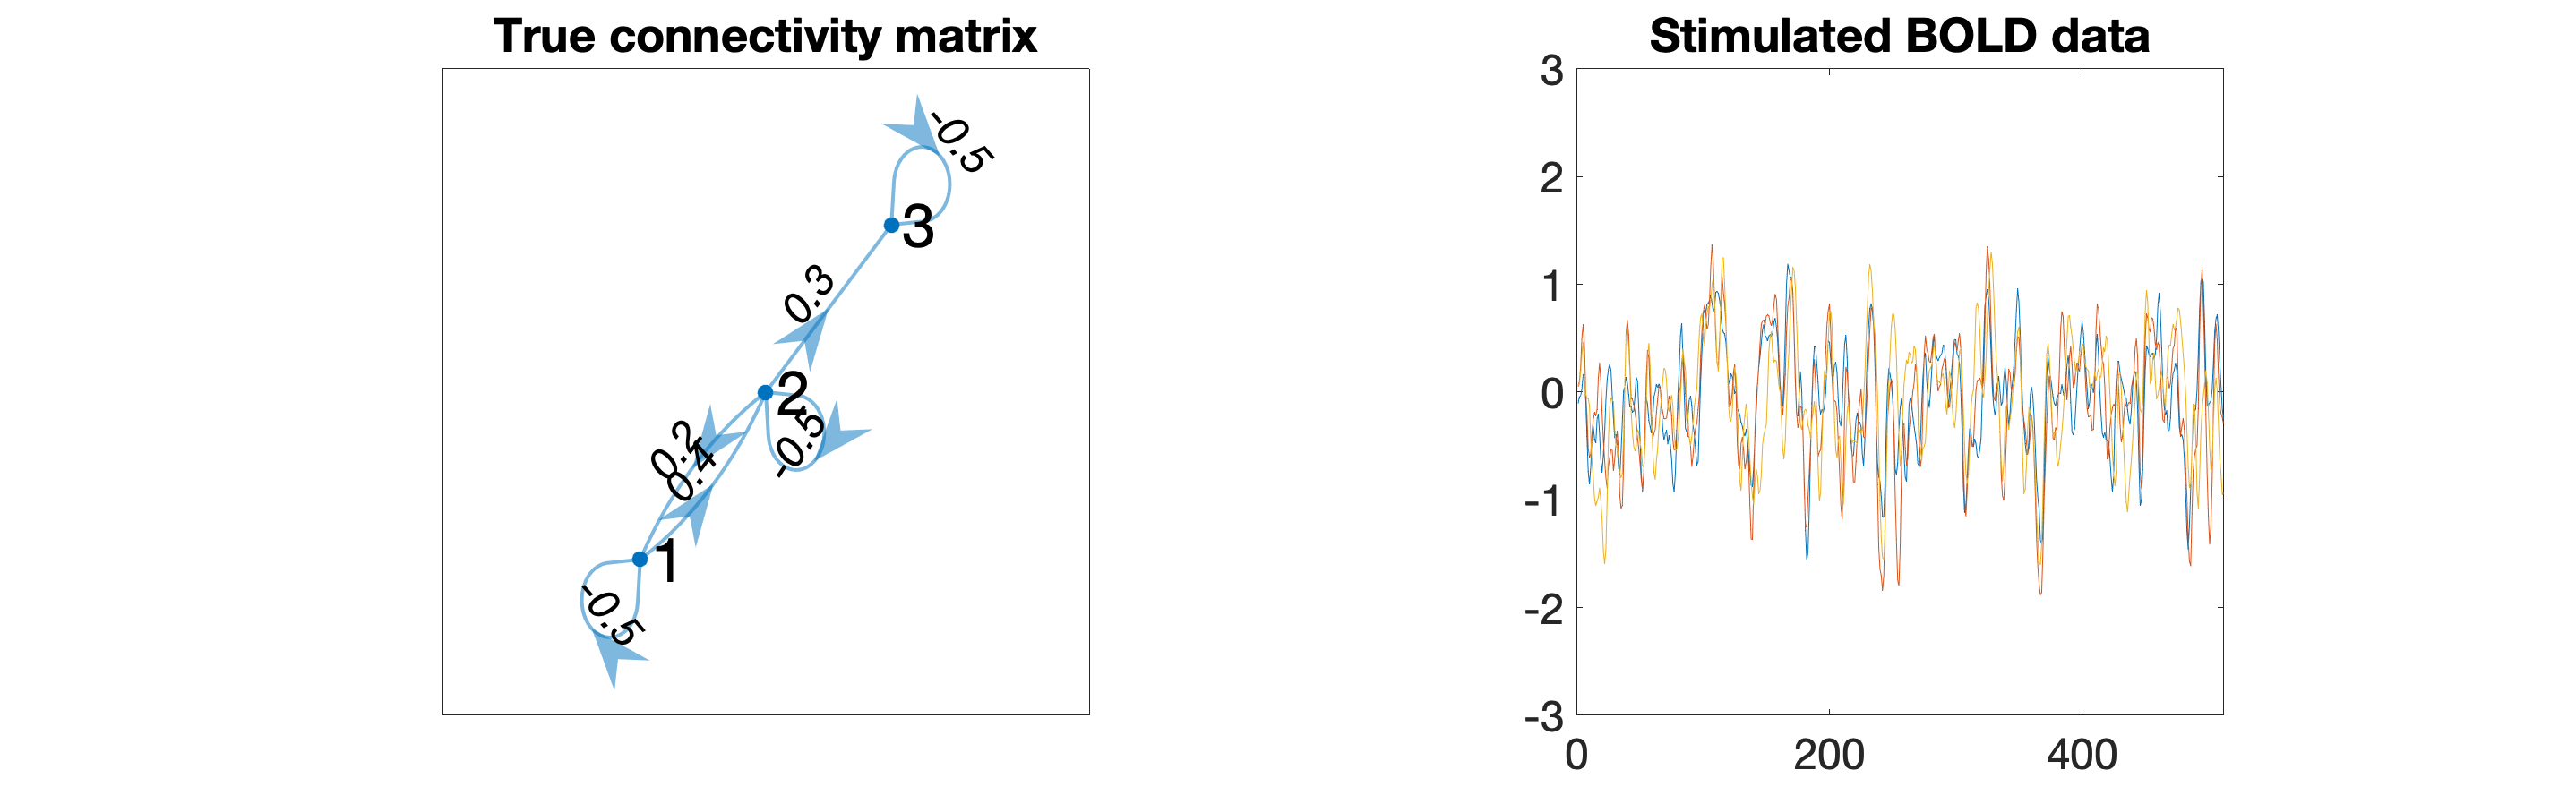

plot_sim_data(DCM)

Remove input so rDCM knows its endogenous activity and set other parameters in the structure that the functions need.

if isfield(DCM, "U")
    DCM = rmfield(DCM,'U');
end

## Invert simulated data using rDCM

### sparse rDCM

Estimate parameters pruning a fully connected adjacency matrix using `tapas_rdcm_sparse.m`

[output_sparse, options_sparse] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


Plot results

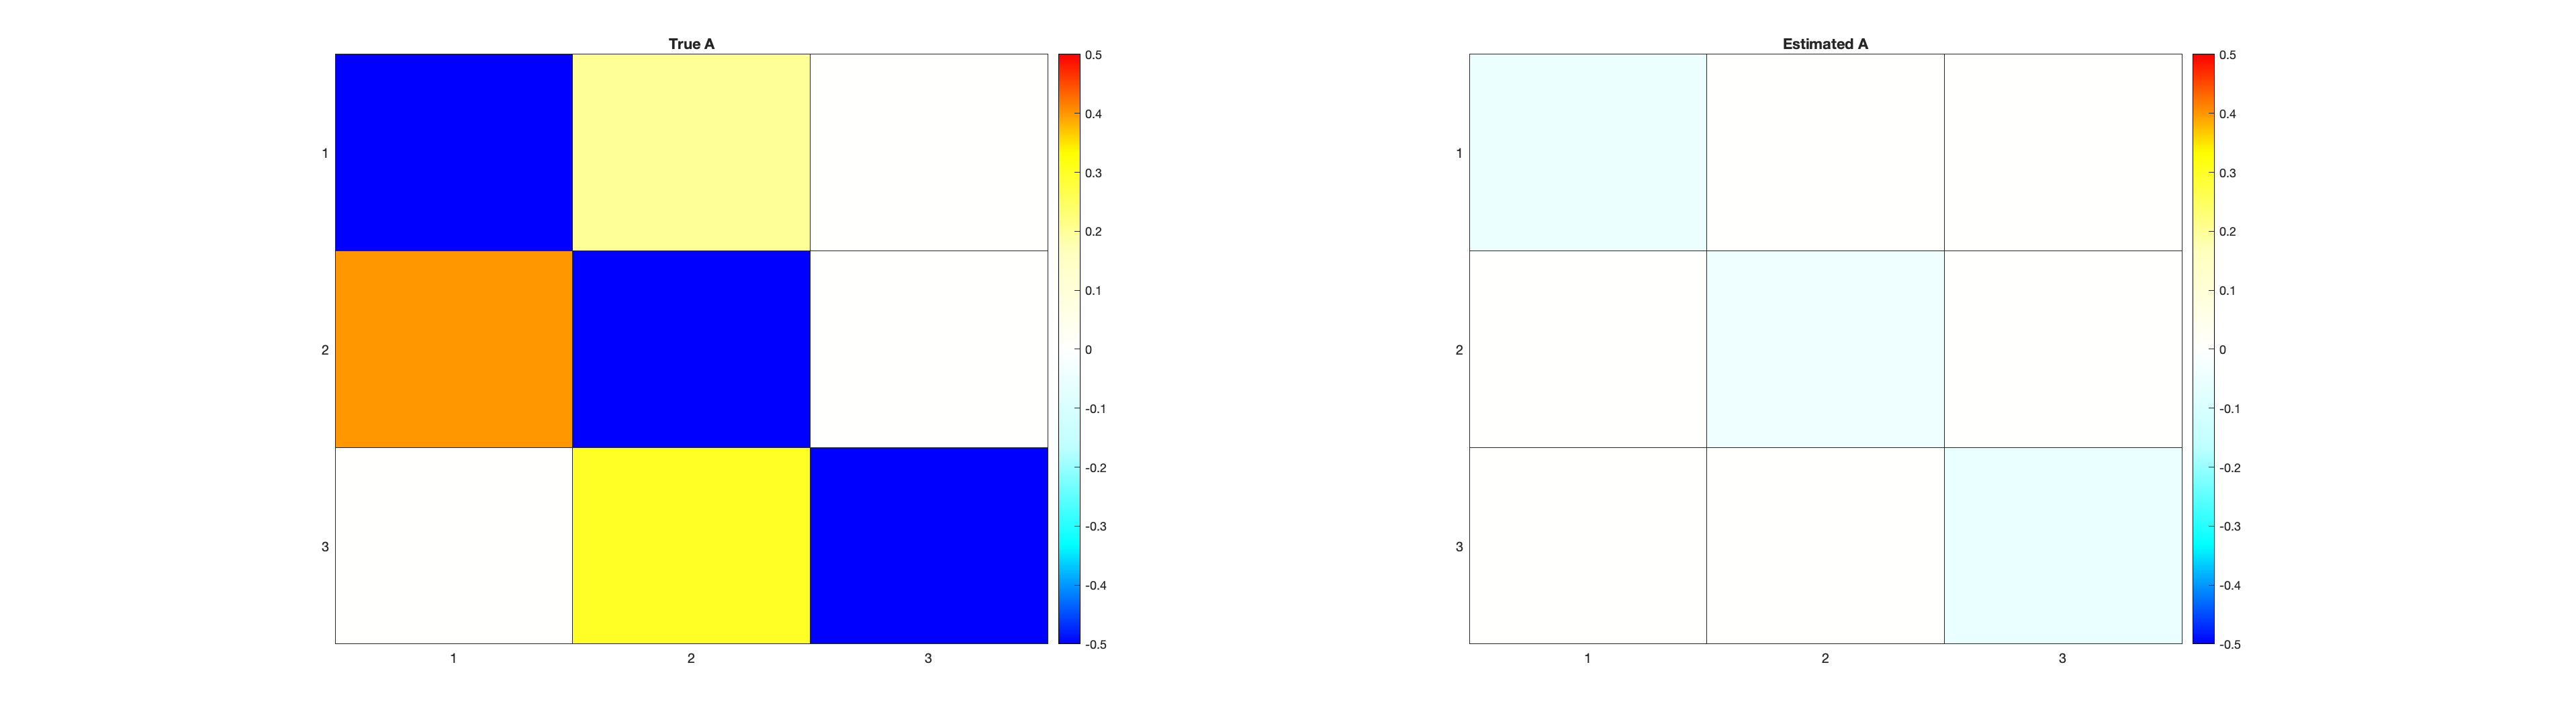

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 2, 2)
h = heatmap(output_sparse.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Does it estimate anything in C?

output_sparse.Ep.C

ans =      0
     0
     0


### ridge rDCM

What if `DCM.a`, the option describing which parameters to estimate,  is not fully connected but set to `logical(pP.A)` i.e. the ridge regression is explicitly told which connections should exist?

DCM.a = logical(DCM.Tp.A);
[output_ridge, options_ridge] = tapas_rdcm_estimate(DCM, type, options, 1);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


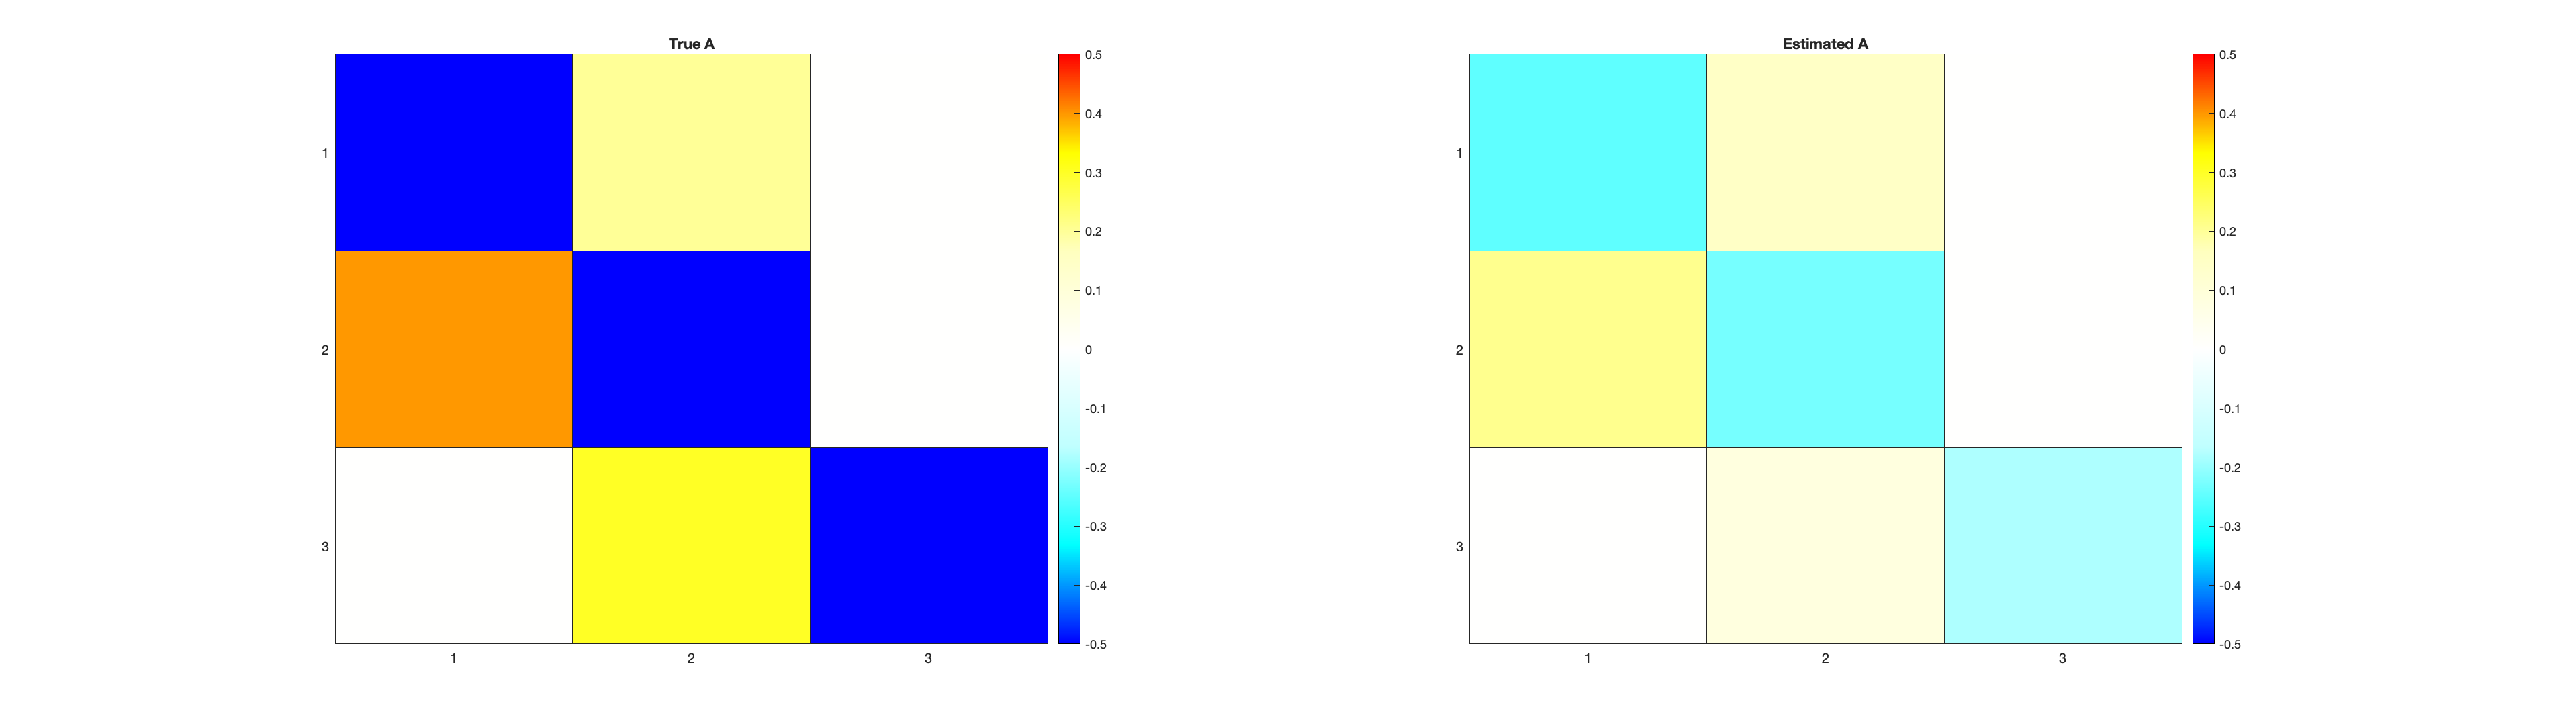

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 2, 2)
h = heatmap(output_ridge.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Is there anything in C?

output_ridge.Ep.C

ans =      0
     0
     0


### Comparison of the sparse and ridge outputs

Does sparse provide a more similar connectivity matrix compared to ridge?

RMSE_sparse = get_rmse(DCM.Tp.A , output_sparse.Ep.A)

RMSE_sparse = 0.3176

RMSE_ridge = get_rmse(DCM.Tp.A , output_ridge.Ep.A)

RMSE_ridge = 0.1904

RMSE_sparse < RMSE_ridge

ans = logical
   0


Does sparse provide a better "fit" compared to deterministic ridge? 

output_sparse.logF > output_ridge.logF

ans = logical
   0


Since this is a linear regression how do predicted versus actual values look for signal in the frequency domain?

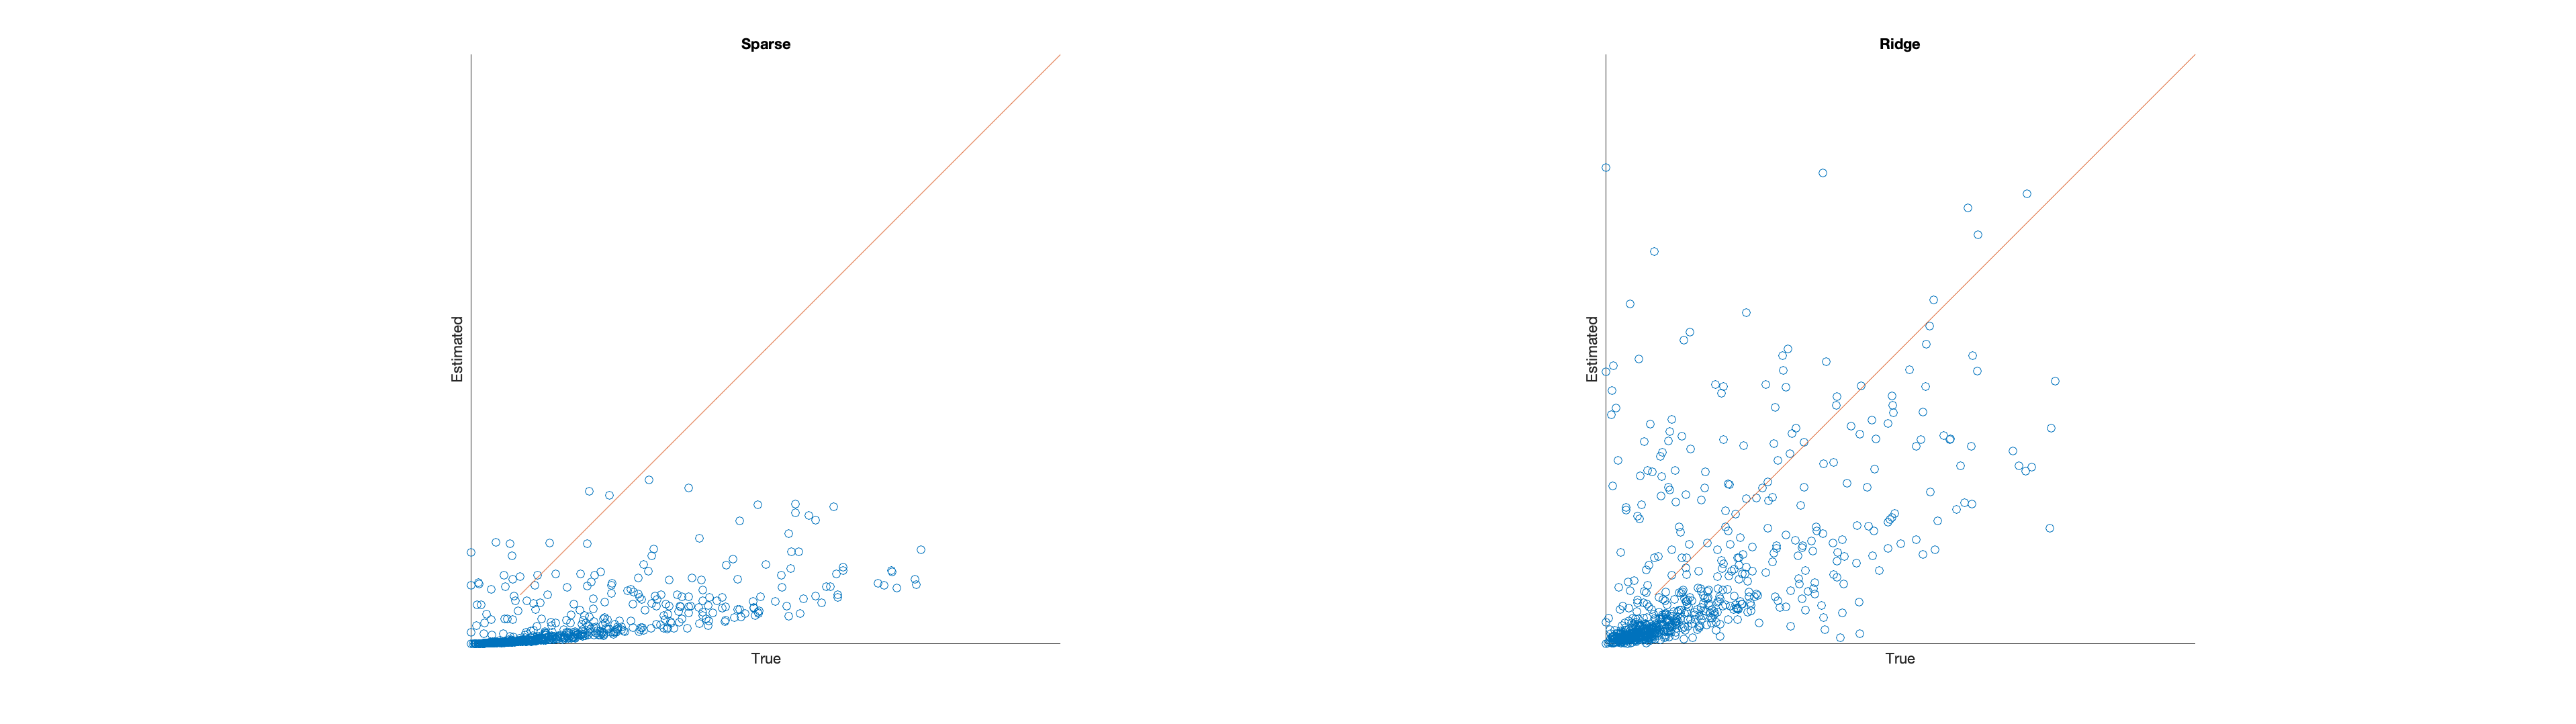

clf
fig = figure();

subplot(1, 2, 1);
scatter(abs(output_sparse.signal.yd_source_fft),abs(output_sparse.signal.yd_pred_rdcm_fft));
hold on 
plot(1:12);
axis square;
set(gca,'XTick',[]);
set(gca,'YTick',[]);
xlabel("True");
ylabel("Estimated");
title("Sparse");

subplot(1, 2, 2);
scatter(abs(output_ridge.signal.yd_source_fft),abs(output_ridge.signal.yd_pred_rdcm_fft));
hold on 
plot(1:12);
axis square;
set(gca,'XTick',[]);
set(gca,'YTick',[]);
xlabel("True");
ylabel("Estimated");
title("Ridge");

set(fig,'Units','normalized','Position',[0 0 1 .5]); 

What do the estimated signals look like in the frequency domain? (Magnitude spectrum plots)

**Add unfiltered FFT of Y to the plots.**

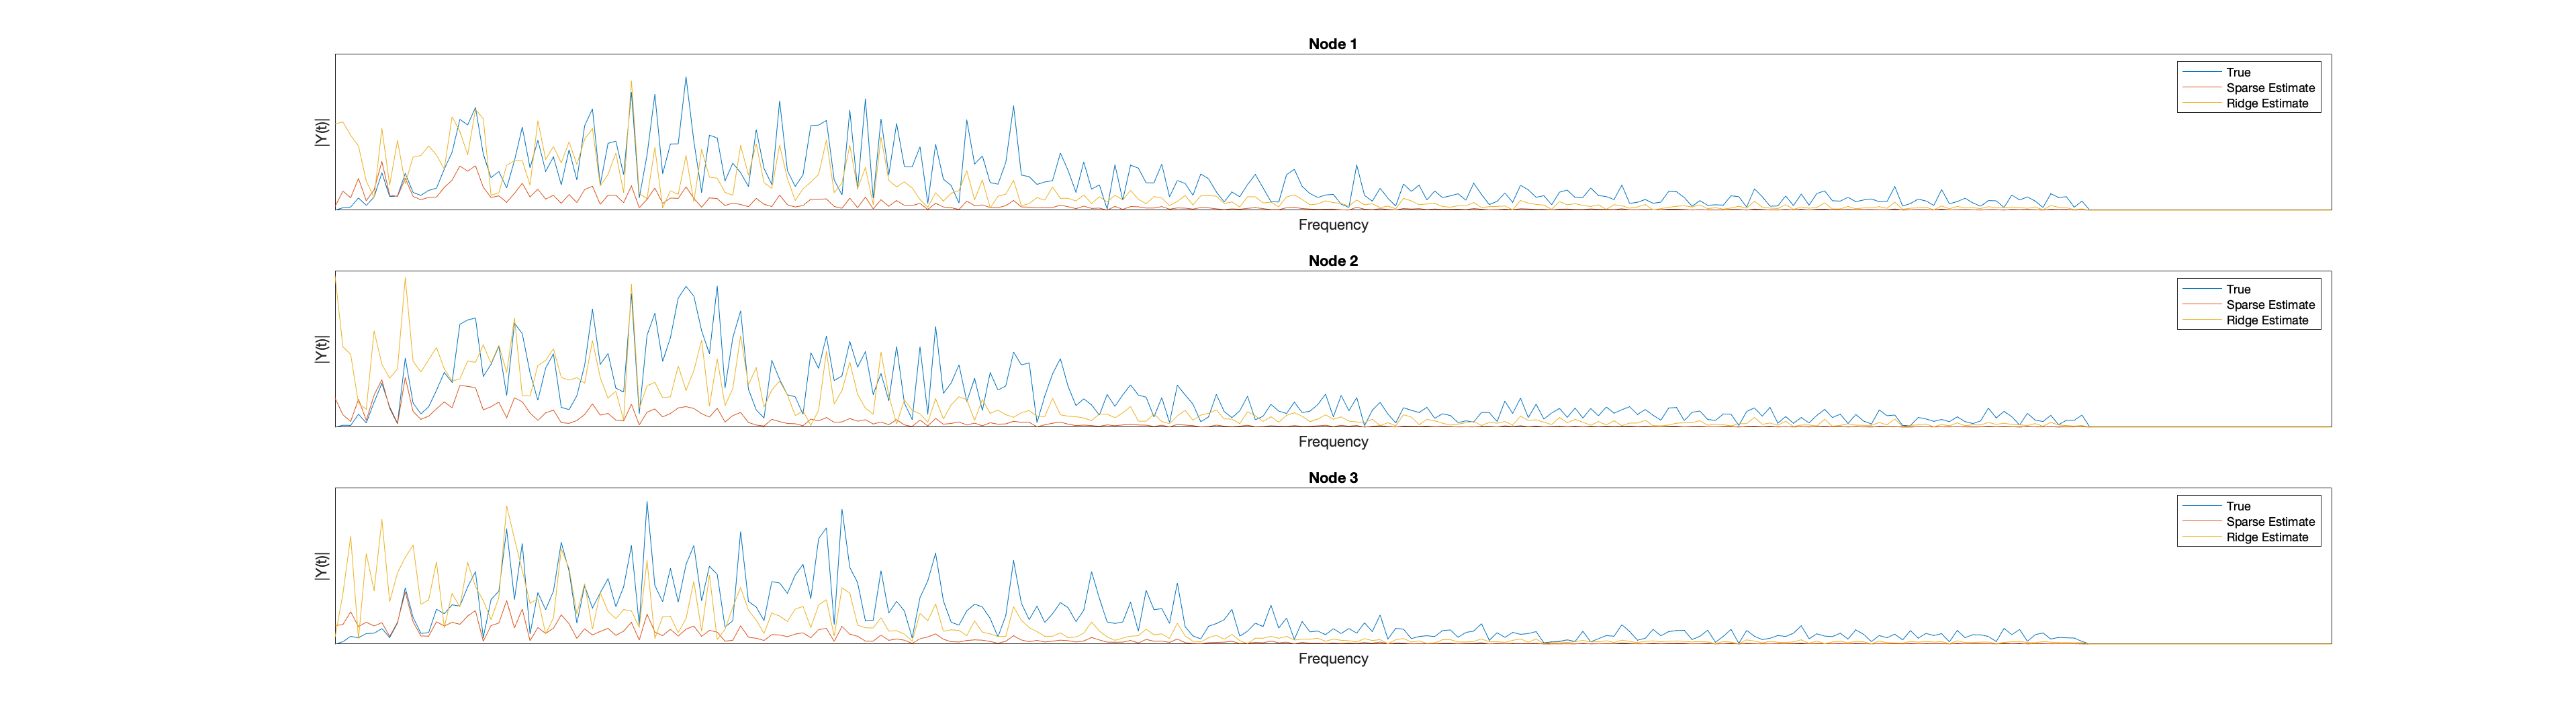

real_comps = 1:(ceil((length(DCM.Y.y)+1)/2));
Fs = options.y_dt;
sampnum = [0: max(real_comps)-1]';
f = sampnum*Fs/length(DCM.Y.y);
clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.yd_source_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    legend("True","Sparse Estimate","Ridge Estimate");
    set(gca,'XTick',[]);
    set(gca,'YTick',[]);
    title(sprintf("Node %.0f", i+1));
    ylabel('|Y(t)|');
    xlabel('Frequency');
end

How do you get from connectivity matrix to the predicted signals above? The values in the estimated connectivity matrix are the coefficients with which to multiply the columns of the design matrix. The sparse estimate is consistently lower than the true signal because the connectivity values estimates are low.

Can I IFFT the predicted frequency domain signals to generate predicted time series?

Note by using the `output.signal.yd_source_fft` won't replicate `output.signal.y_source` because it is **filtered**.

clf
plot(1:512 , output_ridge.signal.y_source(1:512));

Unable to resolve the name output_ridge.signal.y_source.

hold on
plot(1:512, real(ifft(output_ridge.signal.yd_source_fft(1:512))));
legend("True timeseries", "IFFT of yd\_source\_fft");
axis([0 512 -1.5 1.5]);
xlabel('Time');
ylabel('y(t)');

What do the timeseries of IFFT from the estimated frequencies look like?

clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.y_source(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = ifft(cur_y);
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = ifft(cur_y);
    plot(1:stim_options.T, real(cur_y));
    legend("True","Sparse Estimate","Ridge Estimate")
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(sprintf("Node %.0f", i+1))
    xlabel('Time');
    ylabel('y(t)');
end

What if we gave the model a lot more data (i.e. longer time series).

stim_options.T = stim_options.T*10
[DCM, options] = make_DEM_demo_induced_fmri(stim_options);